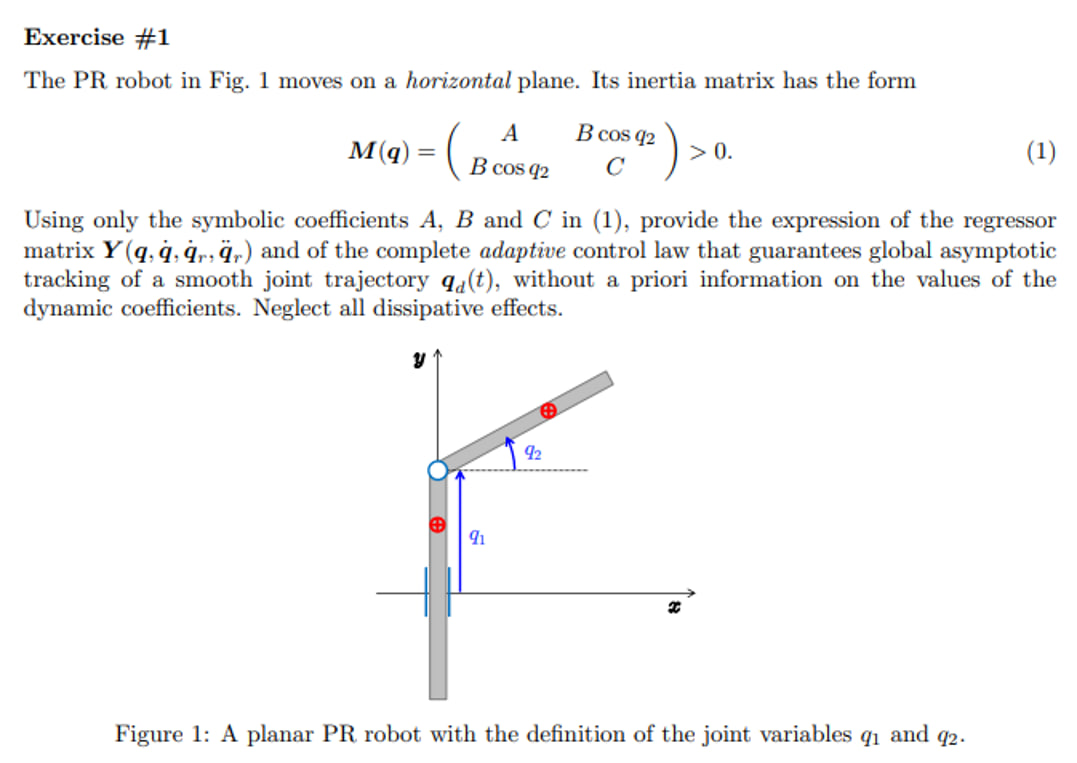

syms q1 q2 q_dot_1 q_dot_2 A B C 
M = [A B*cos(q2);
     B*cos(q2) C;];
% Coriolis and Centrifugal force
q  = [q1; q2;];
dq = [q_dot_1; q_dot_2;];
C = sym(zeros(2,2));

for i = 1:2
    for j = 1:2
        tmp = 0;
        for k = 1:2
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp);  % semplifico
    end
end

c_vec = simplify(C * dq);

disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\left(\begin{array}{cc} 0 & -B\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$


disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\left(\begin{array}{c} -B\,{{\dot{q}}_{2}}^{2}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$


M_subs = [A B*cos(q2);
     B*cos(q2) C;];

Error using catMany>checkDimensions (line 53)
Dimensions of objects being concatenated must match.

Error in catMany (line 12)
[resz, ranges] = checkDimensions(sz, dim);

Error in <a href="matlab:matlab.lang.internal.introspective.errorDocCallback('sym/horzcat', 'C:\Program Files\MATLAB\R2024b\toolbox\symbolic\symbolic\@sym\horzcat.m', 20)" style="

a_vec = [A_hat,B_hat,C_hat]
Y = extract_Y_v3(M_subs,a_vec)

## utils

function Y = extract_Y_v3(Ya, dynamic_symbols)
    % M: inertia matrix
    % C: christoffel matrix
    % G: potential enrgy matrix
    % joint_acceleration: array with joint acceleration
    % this four items are use to build dynamic model

    % dynamic_model: in the form M*ddq + C + G
    % dynamic_coefficient: an array which contain symbol like [ m1+m3 I2
    % ...]
    % dynamic_symbols: how substitute coefficient, so [a1 a2 ... a_n]
    
    Y = sym([]);
    Y_columns = length(dynamic_symbols);
    dynamic_symbols = reshape(dynamic_symbols, 1, Y_columns);

    for i=1:Y_columns
        
        subs_array = zeros(1, Y_columns);
        subs_array(i) = 1;

        Yi = subs(Ya, dynamic_symbols, subs_array);

        Y = [Y, Yi];
    end
    
end